# Inclass assignment 2

% 1. a. fill in this loop with a conditional statement so that it displays
% only the odd numbers

for ii = 1:20
    if mod(ii, 2) == 1
        disp(ii)
    end
end

     1

     3

     5

     7

     9

    11

    13

    15

    17

    19




% b. Write a new loop to display the same odd numbers which doesn't use a conditional statement 

ii = 1;
while ii <= 19
    disp(ii)
    ii = ii + 2;
end

     1

     3

     5

     7

     9

    11

    13

    15

    17

    19



    

% c. display the same odd numbers without a loop or conditional (hint use
%  num2str)


disp(num2str(1:2:19));

1   3   5   7   9  11  13  15  17  19


## 2. Vectorize the following code (that is produce the same result in z

%without using a loop). 

%a. 

for ii = 1:100
    z(ii) = ii*ii;
end

%Vectorized
a = 1:100;
newz = a.*a;

%b. 
z = 0;
for ii = 1:100
    z = z + ii;
end

%Vectorized
newz = sum(1:100);

%c.
xx = rand(50,2);

for ii = 1:50
    z(ii) = sqrt(xx(ii,1)^2+xx(ii,2)^2);
end

%Vectorized
newz = sqrt(sum(xx.*xx,2));

% d. what is the formula in c computing?
%The formula is computing distance from the origin for 50 (x,y)
%coordinates.

## plotting

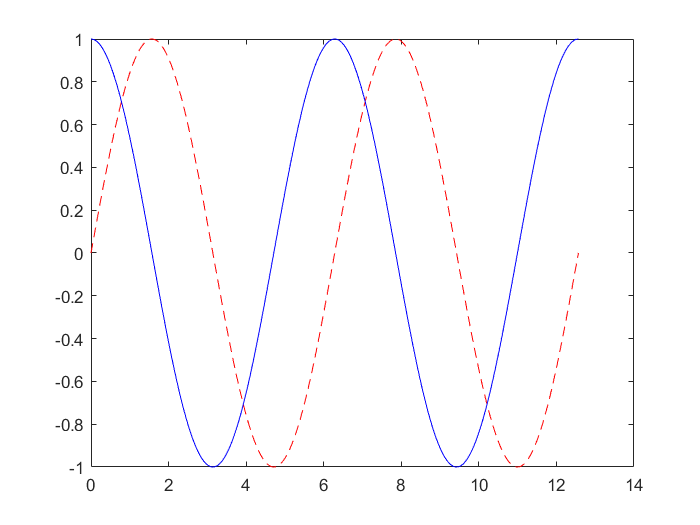

%a. make a plot of sin(x) and cos(x) vs x from x = 0 to 4*pi on the same axis where the graph
%of sin(x) vs x is a red-dashed line and the graph of cos(x) vs x is a
%blue solid line.

x = linspace(0, 4*pi, 1000);
plot(x, sin(x), 'r--', x, cos(x), 'b-')

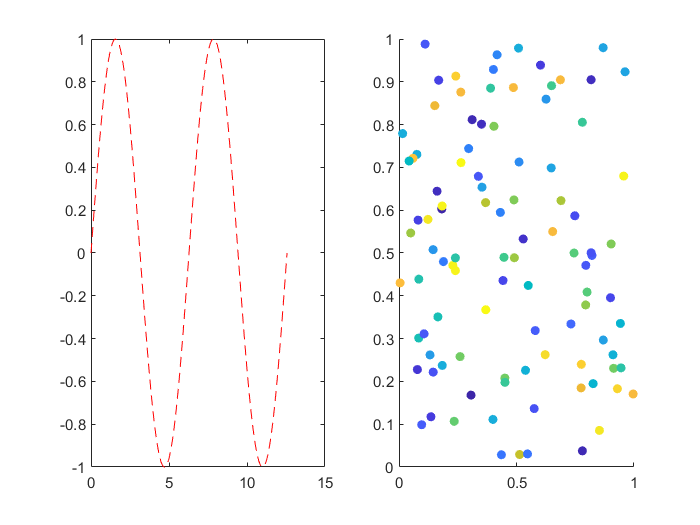


%b. repeat the above but where each graph is in a different subplot in the
% same figure. 

figure;
x = linspace(0, 4*pi, 1000);
subplot(1, 2, 1);
plot(x, sin(x), 'r--')
subplot(1, 2, 2);
plot(x, cos(x), 'b-')

%c. here is some data, imagine they are x and y coordinates for cells. 
xy_dat = rand(100,2);
%plot the data in the xy plane.
scatter(xy_dat(:,1), xy_dat(:,2))

%now imagine there is some fluorescence data corresponding to the same
%cells
fluor = rand(100,1);
% plot the data in the xy plane but color code the data by the fluorescnece
% values. Hint: see the scatter command
scatter(xy_dat(:,1), xy_dat(:,2), 30, fluor, 'filled')